clear;
user=getenv('USERNAME'); %user = 'Guochun Yang';
addpath(genpath('E:\Software\matlab\functions'))
addpath(genpath('C:\softwares\functions'))

datadir = ['C:\Users\' user '\OneDrive - University of Iowa\JiangLab\Experiments\fMRI\fMRI_program\data_all\'];
% savedir = [datadir 'analysis_results_allsubs\'];
savedir = [datadir 'analysis_results_33subs_rng\'];

load([savedir 'datas.mat']);

modelnames = {'base','interaction','sim_mem_pos1','sim_mem_pos1_interaction','addRevSim'};
imodel = 4;
rmpath(genpath(['C:\Users\' user '\OneDrive - University of Iowa\JiangLab\Experiments\MyExperiment\model\']));

addpath(genpath(['C:\Users\' user '\OneDrive - University of Iowa\JiangLab\Experiments\fMRI\fMRI_program\data_all\scripts\Models_avatar']));
savedir_model = [savedir '\' modelnames{imodel} '\'];
if ~exist(savedir_model,'dir'); mkdir(savedir_model);end
load([savedir_model,'\Modelresults.mat']);

beta = Modelresults.betas(:,1:2);
AIC = Modelresults.AICs;
fval = Modelresults.fvals;
x1 = Modelresults.xs(:,1);
x2 = Modelresults.xs(:,2);
x3 = Modelresults.xs(:,3);


nsub = length(datas);
for isub = 1:nsub
    trueSeqs = datas{isub}.trueSeqss;
    probeSeqs = datas{isub}.probeSeqs;
    paras = Modelresults.xs(isub,:);
    [posSelection, taskPrediction, curP, expectedEntropy, simPos, simSteps, ~, curCosts] = Model(trueSeqs, probeSeqs, paras, imodel);
    curCostss{isub} = curCosts;
end

## Table preparation

% todolist: do an LME
dms = [];
RTs = [];
subs = [];
dmEases = [];
pos2tps = [];
simCostsall = [];
for isub = 1:nsub
    trials = [intersect(find(datas{isub}.behCorrect),Modelresults.simtrials{isub});
        intersect(find(datas{isub}.behCorrect),Modelresults.memtrials{isub})]';
    RT = datas{isub}.behRT(trials);
    RTs = [RTs;RT];
    dm0 = Modelresults.dm0s{isub}; dm0(:,2) = dm0(:,2)*Modelresults.xs(isub,2);
    dm = dm0(trials,:);
    dms = [dms;dm];
    sub = ones(size(RT))*isub;
    subs = [subs;sub];
    dmEase = Modelresults.dmEases(isub,trials);
    simCostall = Modelresults.curCostsss{isub}{2}(trials)';

    
    dmEases = [dmEases;dmEase'];
    pos2tp = Modelresults.pos2tpss(isub,trials);

    %test the idx for each +-1
    trialslastsim = trials(find(pos2tp==-1));
    trialsfirstmem = trials(find(pos2tp==1));
    for iseq = 1:2
        for ipos = 2:5
            idx0 = intersect(find(datas{isub}.probeSeqs(1,:) == iseq),find(datas{isub}.probeSeqs(2,:) == ipos));
            nreplays(iseq,ipos) = length(intersect(Modelresults.simtrials{isub},idx0));
            if ~isempty(intersect(trialslastsim,idx0))
                idxlastsims0(isub,iseq,ipos) = intersect(trialslastsim,idx0);
            else
                idxlastsims0(isub,iseq,ipos) = nan;
            end
            if ~isempty(intersect(trialsfirstmem,idx0))
                idxfirstmem0(isub,iseq,ipos) = intersect(trialsfirstmem,idx0);
            else
                idxfirstmem0(isub,iseq,ipos) = nan;
            end
        end
    end

    pos2tps = [pos2tps;pos2tp'];
    simCostsall = [simCostsall;simCostall];
end
regnames = Modelresults.regnamess{1};
tbl = array2table([dmEases,dms,RTs,subs,pos2tps,simCostsall]);
tbl.Properties.VariableNames = ['Ease',regnames,{'RT','sub','pos2tp','simCostall'}];
tbl.Ease_R = tbl.Ease.*tbl.simtrial;
tbl.Ease_M = tbl.Ease.*tbl.memtrial;

%z
tbl.Easez = (tbl.Ease - nanmean(tbl.Ease))/nanstd(tbl.Ease);
tbl.simCostz = (tbl.simCost- nanmean(tbl.simCost))/nanstd(tbl.simCost);
tbl.expEntz = (tbl.expEnt - nanmean(tbl.expEnt))/nanstd(tbl.expEnt);
tbl.interactionz = (tbl.interaction - nanmean(tbl.interaction))/nanstd(tbl.interaction);
tbl.trialz = (tbl.trial - nanmean(tbl.trial))/nanstd(tbl.trial);
idx_simtrial = find(tbl.simtrial==1);
tbl.Ease_Rz = zeros(size(tbl.Ease));
tbl.Ease_Rz(idx_simtrial) = (tbl.Ease(idx_simtrial) - nanmean(tbl.Ease(idx_simtrial)))/nanstd(tbl.Ease(idx_simtrial));
idx_memtrial = find(tbl.memtrial==1);
tbl.Ease_Mz = zeros(size(tbl.Ease));
tbl.Ease_Mz(idx_memtrial) = (tbl.Ease(idx_memtrial) - nanmean(tbl.Ease(idx_memtrial)))/nanstd(tbl.Ease(idx_memtrial));
tbl.trialtype = tbl.simtrial-tbl.memtrial;
tbl.pos2tpz = (tbl.pos2tp - nanmean(tbl.pos2tp))/nanstd(tbl.pos2tp);
tbl.simCostallz = (tbl.simCostall - nanmean(tbl.simCostall))/nanstd(tbl.simCostall);


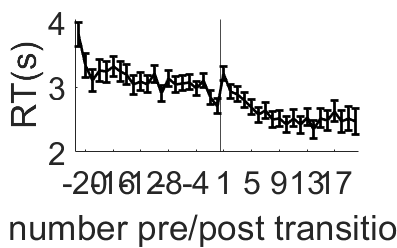

%plot the RT across the 10 trials
lme0 = fitlme(tbl,'RT ~ 1+(1|pos2tp)');

[~,~,stats] = randomEffects(lme0);
posRT = stats.Estimate(find(ismember(stats.Group,'pos2tp'))) + lme0.Coefficients.Estimate(1);
posSE = stats.SEPred(find(ismember(stats.Group,'pos2tp')));
poses = unique(tbl.pos2tp(find(~isnan(tbl.pos2tp))));

%add mean of raw RT
for i = 1:length(poses)
    ntrial(i) = length(find(tbl.pos2tp == poses(i)));
    posRTraw(i) = nanmean(tbl.RT(tbl.pos2tp == poses(i)));
end
idxpos = find(ntrial>20); %remove points with too few trials
poses_remain = poses(idxpos);

% test the source of difference between the two measures (I guess the
% fitted RT average each subject with equal weight) with the first position
for isub = 1:nsub
    idx = intersect(find(tbl.pos2tp == -23),find(tbl.sub == isub));
    ntrialsub(isub) = length(idx);
    posRTmeansub(isub) = nanmean(tbl.RT(idx));
end

plotrawonly = 1;
addraw = 0;
figure('Position',[200 200 800 500]);
if plotrawonly < 1
    errorbar(posRT(idxpos),posSE(idxpos),'-k','LineWidth',2);
else
    errorbar(posRTraw(idxpos),posSE(idxpos),'-k','LineWidth',2);
end
if addraw; hold; plot(posRTraw(idxpos),'-b','LineWidth',2); end
transpoint = (find(poses_remain==-1)+find(poses_remain==1))/2;
for i = 1:length(poses_remain)
    xticklab{i} = num2str(poses_remain(i));
end
xline(transpoint,'-k')
if addraw; legend({'Fitted RT','raw RT'},'Location','southwest');end
if length(poses_remain) > 10
%     idx_xticks = [2:3:23,24:3:length(poses)];
    idx_xticks = [2:4:length(poses_remain)];
    xticks(idx_xticks);
    xticklabels(xticklab(idx_xticks));
else
    xticks([1:1:length(poses_remain)]);
    xticklabels(xticklab);  
end
xlim([0.5 length(poses_remain)+0.5])
ylim([2 4.05])
box off;
if addraw
    ylabel('RT(s)');
elseif plotrawonly
    ylabel('RT(s)');
else
    ylabel('Fitted RT(s)');
end
xlabel('Trial number pre/post transition point')
set(gca,'fontsize',24)
xtickangle(0);
if addraw
    print('-dpng','-r200',[savedir_model 'RTall_prepost_addraw.png'])
elseif plotrawonly
    print('-dpng','-r200',[savedir_model 'RTall_prepost_rawonly.png'])
else
    print('-dpng','-r200',[savedir_model 'RTall_prepost.png'])
%     print('-dpng','-r200',[savedir 'residualRTall_prepost.png'])
end

for i = 1:length(poses)
    idx = find(tbl.pos2tp==poses(i));
    for isub = 1:nsub
        idx_sub = intersect(find(tbl.sub == isub),idx);
        posRT_sub(isub,i) = mean(tbl.RT(idx_sub));
    end
end
switchcost = posRT_sub(:,24) - posRT_sub(:,23);
save([savedir 'switchcost_ind.mat'],'switchcost');
figure('Position',[200 200 300 400]);
for isub = 1:nsub
    if ~ishold; hold; end
    plot(posRT_sub(isub,23:24),'-');
end

Current plot held


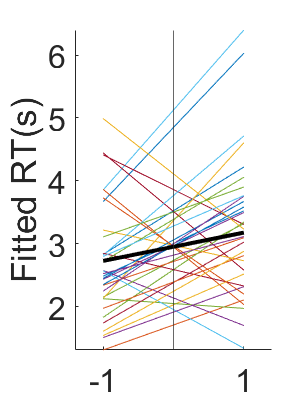

plot(posRT(23:24),'-k','LineWidth',3);
xlim([0.8 2.2]);
xline(1.5)
box off;
set(gca,'fontsize',24)
xticks([1 2]);
xticklabels({'-1','1'})
% xlabel('Trial number')
% ylabel('RT(s)')
ylabel('Fitted RT(s)')
% % print('-dpng','-r200',[savedir 'RT+-1_prepost.png'])
print('-dpng','-r200',[savedir 'RT+-1_prepost_fitRT.png'])

% double check the trial number of +-1 trials！！！！！！
for isub=1:length(datas)
    datas{isub}.subNo %297626;
    [idxpre_conds,idxpost_conds] = deal([]);
    for iseq = 1:2
        for ipos = 2:5
            idxcond = intersect(find(datas{isub}.probeSeqs(1,:) == iseq), ...
                find(datas{isub}.probeSeqs(2,:) == ipos));

            idxpre = exp(tbl.trial(intersect(find(tbl.sub==isub), find(tbl.pos2tp==-1))));
            idxpre = round(idxpre);
            idxpre_cond = intersect(idxcond,idxpre);
            idxpost = exp(tbl.trial(intersect(find(tbl.sub==isub), find(tbl.pos2tp==1))));
            idxpost = round(idxpost);
            idxpost_cond = intersect(idxcond,idxpost);

%             Modelresults.pos2tpss(isub,idxcond)
            idxpre_conds = [idxpre_conds;idxpre_cond];
            idxpost_conds = [idxpost_conds;idxpost_cond];
        end
    end

ans = 297626

ans = 865258

ans = 900294

ans = 176009

ans = 840914

ans = 800290

ans = 44586

ans = 497627

ans = 186201

ans = 784847

ans = 822030

ans = 974048

ans = 148023

ans = 509291

ans = 299988

ans = 872699

ans = 2519390

ans = 8078510

ans = 720490

ans = 456199

ans = 446983

ans = 555530

ans = 707328

ans = 130785

ans = 730666

ans = 653150

ans = 407180

ans = 784426

ans = 681160

ans = 686402

ans = 142464

ans = 865002

ans = 642305

ans = 169609

    trial.pres{isub} = idxpre_conds;
    trial.posts{isub} = idxpost_conds;
    trial.sub(isub) = datas{isub}.subNo;
end


tbl2trial = tbl(find(abs(tbl.pos2tp)<2),:);
% lme_real = fitlme(tbl2trial,'RT~pos2tp+(pos2tp-1|sub)')
lme_real = fitlme(tbl2trial,'RT~pos2tp+(1|sub)+(pos2tp-1|sub)')

lme_real = Linear mixed-effects model fit by ML

Model information:
    Number of observations             283
    Fixed effects coefficients           2
    Random effects coefficients         66
    Covariance parameters                3

Formula:
    RT ~ 1 + pos2tp + (1 | sub) + (pos2tp | sub)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    957.92    976.15    -473.96          947.92  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF     pValue      Lower       Upper  
    {'(Intercept)'}          2.979     0.13672    21.789    281           0      2.7099     3.2481
    {'pos2tp'     }        0.26659     0.10777    2.4737    281    0.013963    0.054452    0.47874

Random effects covariance parameters (95% CIs):
Group: sub (33 Levels)
    Name1                  Name2                  Type           Est

lme_real2 = fitlme(tbl2trial,['RT~pos2tp+simCost+expEnt+interaction+trial+' ...
    '(1|sub)+(pos2tp-1|sub)+(simCost-1|sub)+(expEnt-1|sub)+(interaction-1|sub)+(trial-1|sub)']);
[~,~,stat] = fixedEffects(lme_real2,'DFmethod','satterthwaite')
idx_pos2tp = find(ismember(stat.Name,'pos2tp'));
p_cor = (1-tcdf(stat.tStat(idx_pos2tp),stat.DF(idx_pos2tp)))*2; %we don't have a side hypothesis
b_real = lme_real.Coefficients.Estimate(2)

b_real = 0.2666

b_real2 = lme_real2.Coefficients.Estimate(6)

b_real2 = 0.3972


%get partial eta square
% residual = lme_real.residuals;
% y_fit_fixed = [ones(size(tbl2trial,1),1),tbl2trial.pos2tp]*lme_real.Coefficients.Estimate;
% eta_p = var(y_fit_fixed)/(var(y_fit_fixed)+var(residual)); %0.0172
eta_p = geteffectfromfitlme(lme_real2,'pos2tp')

eta_p = 0.0602

% permutation: test if the increase at the transition point is random error
if isempty(gcp("nocreate")); parpool; end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 10).


nperm = 5000;
parfor iperm = 1:nperm
    iperm
    pos2tp_perms = zeros(nsub,240);
    for isub = 1:nsub
        pos2tp_perm = zeros(1,240);
        pos2tp_perm(find(datas{isub}.behCorrect==0)) = nan;
        for iseq = 1:2
            for ipos = 1:5    
                idx = intersect(find(datas{isub}.probeSeqs(1,:) == iseq),find(datas{isub}.probeSeqs(2,:) == ipos));
                transpoint = randsample(-0.5:1:24.5,1); %here we define transpoint+0.5 as the transpoint
                if ismember(transpoint,[0.5:1:23.5])
                    pos2tp_perm0 = [1:24] - transpoint;
                    pos2tp_perm0(find(pos2tp_perm0<0)) = pos2tp_perm0(find(pos2tp_perm0<0)) - 0.5;
                    pos2tp_perm0(find(pos2tp_perm0>0)) = pos2tp_perm0(find(pos2tp_perm0>0)) + 0.5;
                    pos2tp_perm(idx) = pos2tp_perm0;
                else
                    pos2tp_perm(idx) = nan;
                end
            end
        end
        pos2tp_perms(isub,:) = pos2tp_perm;
    end
    % do LME
    behRTs = [];
    pos2tp_perms2 = [];
    subs = [];
    [simCost,expEnt,interaction,trial] = deal([]);
    for isub = 1:nsub
        trials = find(datas{isub}.behCorrect)';
        behRTs = [behRTs; datas{isub}.behRT(trials)];
        pos2tp_perms2 = [pos2tp_perms2; pos2tp_perms(isub,trials)'];
        subs = [subs;ones(length(trials),1)*isub];
        simCost = [simCost;Modelresults.dm0s{isub}(trials,1)];
        expEnt = [expEnt;Modelresults.dm0s{isub}(trials,2)];
        interaction = [interaction;Modelresults.dm0s{isub}(trials,5)];
        trial = [trial;Modelresults.dm0s{isub}(trials,6)];
    end
    tbl_perm = table(behRTs,pos2tp_perms2,subs,simCost,expEnt,interaction,trial);
    tbl_perm2 = tbl_perm(abs(pos2tp_perms2)<2,:);
%     lme_perm = fitlme(tbl_perm2,'behRTs~pos2tp_perms2+(1|subs)+(pos2tp_perms2-1|subs)');
    lme_perm = fitlme(tbl_perm2,['behRTs~pos2tp_perms2+simCost+expEnt+interaction+trial+' ...
        '(1|subs)+(pos2tp_perms2-1|subs)+(simCost-1|subs)+(expEnt-1|subs)+(interaction-1|subs)+(trial-1|subs)']);
    b_perm(iperm) = lme_perm.Coefficients.Estimate(2);
end


ans =

    25


ans =

    50


ans =

    75


ans =

   100


ans =

   125


ans =

   150


ans =

   175


ans =

   200


ans =

   225


ans =

   250


ans =

    24


ans =

    49


ans =

    74


ans =

    99


ans =

   124


ans =

   149


ans =

   174


ans =

   199


ans =

   224


ans =

   249


ans =

    23


ans =

    48


ans =

    98


ans =

   248


ans =

    73


ans =

   148


ans =

   198


ans =

   223


ans =

    22


ans =

   123


ans =

   173


ans =

    21


ans =

    72


ans =

    97


ans =

   147


ans =

   197


ans =

   222


ans =

    47


ans =

    71


ans =

   172


ans =

   196


ans =

   221


ans =

   247


ans =

    20


ans =

    46


ans =

    96


ans =

   122


ans =

   146


ans =

   171


ans =

   195


ans =

    70


ans =

   220


ans =

    19


ans =

    45


ans =

    69


ans =

    95


ans =

   121


ans =

   145


ans =

   170


ans =

   194


ans =

   219


ans =

   246


ans =



save([savedir '\b_perm_regother.mat'],'b_perm');

if ~exist('b_perm','var'); load([savedir '\b_perm.mat']); end
p = length(find(b_perm>b_real))/nperm

p = 0

p2 = length(find(b_perm>b_real2))/nperm

p2 = 0


figure('Position',[0 0 400 600]);
h = histogram(b_perm,50);
h.FaceColor = [0.5 0.5 0.5]; 
h.EdgeColor = 'k'; 
hold;

Current plot held


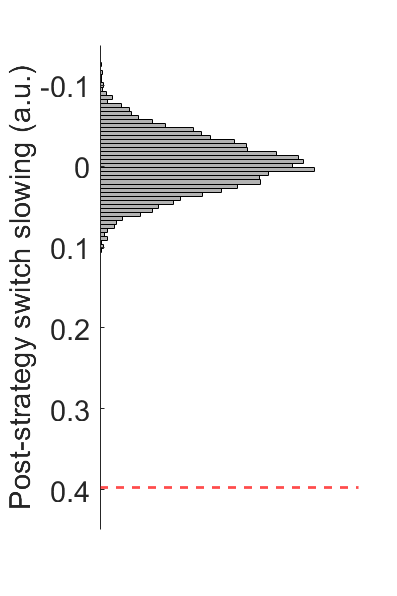

xline(b_real2,'--r','LineWidth',2);
xlim([-0.15 0.45])
box off;
view([90 90])
set(gca,'FontSize',22);
xlabel('Post-strategy switch slowing (a.u.)','FontSize',22);
set(gca,'YColor','none');
% print('-dpng','-r200',[savedir 'switch_cost_distribution_vertical.png']);
print('-dpng','-r200',[savedir 'switch_cost_distribution_vertical_regother.png']);

% Calculate the proportion of subjects using replay strategy
simPos_all = Modelresults.simPos_all;

idx =    176
   177
   178
   179
   180
   181
   182
   183
   184
   185


seqs = {'A','B'}
for iseq = 1:2

seqs = 1×2 cell array
    {'A'}    {'B'}


    for ipos = 1:5
        for isub = 1:nsub
            Xn = intersect(find(datas{isub}.probeSeqs(1,:) == iseq), find(datas{isub}.probeSeqs(2,:) == ipos)); %A4
            simulatedtrial = find(simPos_all(isub,:) ~= datas{isub}.probeSeqs(2,:)); % based on 240 trials
            pos1trial = find(datas{isub}.probeSeqs(2,:) == 1);
            memorytrial = setdiff(find(simPos_all(isub,:) == datas{isub}.probeSeqs(2,:)),pos1trial);
            trialtype = ones(1,240);
            trialtype(memorytrial) = 0; % sim is 1 and mem is 0
            trialtype(pos1trial) = nan;
            trialtypes(isub,:) = trialtype;
            Xns(isub,:) = trialtype(1,Xn);
        end
        meantrialtype = nanmean(Xns,1);
%         figure;
%         imagesc(Xns);
%         title([seqs{iseq},num2str(ipos)]);
        % print('-dpng','-r300',[])
        mXs(:,iseq,ipos) = nanmean(Xns,1);
        seXs(:,iseq,ipos) = nanstd(Xns,1);
        mXss(:,:,iseq,ipos) = Xns;
    end
end

## plot the change of trial type (ratio)

% for A+B
figure;
for iseq = 1:2
    for ipos = 2:5
        plot(mXs(:,iseq,ipos),'-');
        if iseq == 1 && ipos == 2
            hold;
        end
    end
end

Current plot held


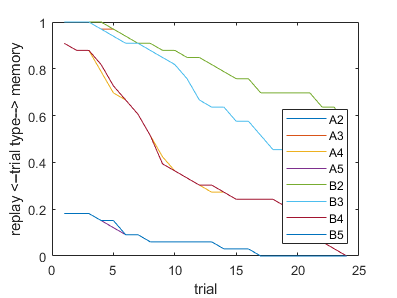

ylabel('replay <--trial type--> memory')
xlabel('trial')
legend({'A2','A3','A4','A5','B2','B3','B4','B5'},'Location','southeast')


% for average of A and B
figure('Position',[0 0 700 600]);
colors = {'r','b','g','k'};
for ipos = 2:5
    plot(squeeze(mean(mXs(:,:,ipos),2)),'-',"LineWidth",2,'Color',colors{ipos-1})
    if ipos == 2
        hold;
    end
end

Current plot held


ylim([0,1.05])
box off;
% ylabel('Trial type ratio (Replay:Memory)')
ylabel('Proportion of replay strategy')
xlabel('Trial')
leg = legend({'2','3','4','5'},'Location','northeast','NumColumns',2)

leg =   Legend (2, 3, 4, 5) with properties:

         String: {'2'  '3'  '4'  '5'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7248 0.8464 0.1657 0.0608]
          Units: 'normalized'

  Show all properties


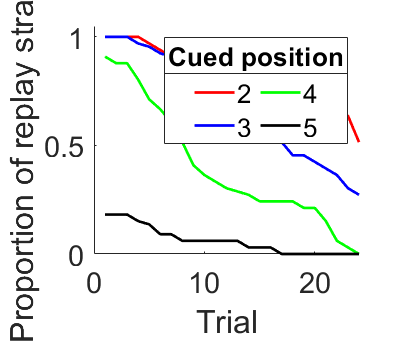

title(leg,'Cued position')
set(gca,'FontSize',22)
print('-dtiff','-r300',[savedir_model '\TrialTypeRatio.tiff'])

group1 =      1     2     4     6     7     8    11    12    14    15    18    20    22    25    28    32    33


group2 =      3     5     9    10    13    16    17    19    21    23    24    26    27    29    30    31


Current plot held


leg =   Legend (position) with properties:

         String: {'2'  '3'  '4'  '5'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 12.6000
       Position: [0.2965 0.6025 0.1321 0.2726]
          Units: 'normalized'

  Show all properties


Current plot held


group1 =      1     2     3     4     6     7     8    11    12    14    15    18    20    22    25    28    33


group2 =      5     9    10    13    16    17    19    21    23    24    26    27    29    30    31    32


Current plot held


leg =   Legend (2, 3, 4, 5) with properties:

         String: {'2'  '3'  '4'  '5'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.3267 0.7532 0.1018 0.1464]
          Units: 'normalized'

  Show all properties


Current plot held


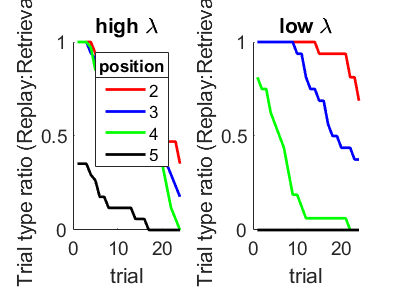

group1 =      1     2     3     6     7     8     9    11    12    15    17    19    20    22    25    27    33


group2 =      4     5    10    13    14    16    18    21    23    24    26    28    29    30    31    32


Current plot held


leg =   Legend (2, 3, 4, 5) with properties:

         String: {'2'  '3'  '4'  '5'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.3267 0.7532 0.1018 0.1464]
          Units: 'normalized'

  Show all properties


Current plot held


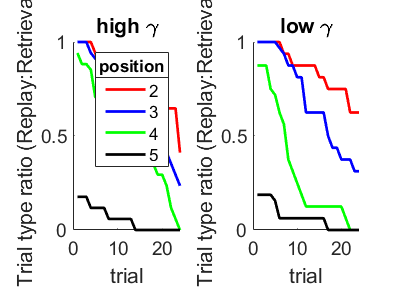

% plot proportion of trials using replay for each subject
figure;

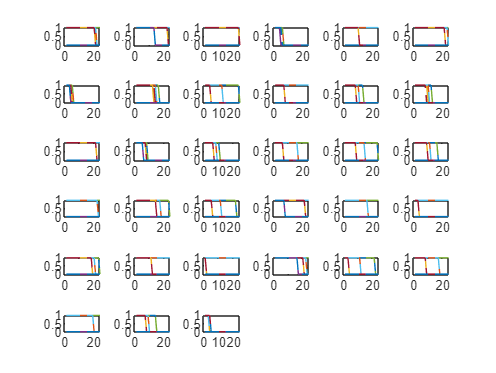

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held


for isub = 1:nsub
    if isub < nsub+1
        nexttile;
        for iseq = 1:2
            for ipos = 2:5
                if iseq == 1
                    plot(mXss(isub,:,iseq,ipos),'-');
                else
                    plot(mXss(isub,:,iseq,ipos),'--');
                end
                if iseq == 1 && ipos == 2
                    hold;
                end
            end
        end
    else
        ax = nexttile; ax = nexttile;
        plot(rand(5,240),'-');hold;
        plot(rand(5,240),'--');
        axis off;
%         ax.Visible = false;
        delete(ax); 
        ylabel('replay <--trial type--> memory')
        xlabel('trial')
        legend({'A2','A3','A4','A5','B2','B3','B4','B5'},'Location','southeast')
    end
end

% plot the two costs
for isub = 1:nsub
    trueSeq = datas{isub}.trueSeqs;
    probeSeqs = datas{isub}.probeSeqs;
    paras = Modelresults.xs(isub,:);
    curCostss = Modelresults.curCostsss{isub};                       
%     [~, ~, ~, ~, ~, ~, ~, curCostss] = Model(trueSeqs, probeSeqs, paras, imodel);
    for itrial = 1:240
        costs(isub,itrial,1) = curCostss{1}{itrial}(1);
        costs(isub,itrial,2) = curCostss{1}{itrial}(end);
    end
    simCosts(isub,:) = curCostss{2};
    memCosts(isub,:) = curCostss{3};
    for iseq = 1:2
        for ipos = 1:5
            postrial = intersect(find(probeSeqs(1,:) == iseq), find(probeSeqs(2,:) == ipos));
            postrials(isub,iseq,ipos,:) = postrial;
            simCostsbypos(isub,iseq,ipos,:) = curCostss{2}(postrial);
            memCostsbypos(isub,iseq,ipos,:) = curCostss{3}(postrial);
    %         postrials(ipos,:) = postrial;
    %         costsbypos(isub,ipos,:) = squeeze(mean(costs(isub,postrial,:),3));
        end
    end
end
meansimCosts = squeeze(mean(mean(simCostsbypos,2),1));
meanmemCosts = abs(squeeze(mean(mean(memCostsbypos(2,:,:,:),2),1)));

if 1 == 1
    % plot an example subject with all positions averaged
    % costm = squeeze(nanmean(costs(:,:,:),1));
    savedir = [savedir_model '\CostChange'];
    if ~exist(savedir,'dir'); mkdir(savedir);end
    for subexp = 1:nsub %32
        curCostss = Modelresults.curCostsss{subexp};
        simCost = curCostss{2};
        memCost = curCostss{3};
        % for ipos = 1:5
        %     postrialAB = sort(reshape(postrials(subexp,:,ipos,:),1,48));
        %     costms(ipos,:,:) = squeeze(costs(subexp,postrialAB,:));
        % end
        seqs = {'A','B'};
        for iseq = 1:2
            figure;
            colors = {'r','b','g','k'};
            for ipos = 2:5
                postrial = squeeze(postrials(subexp,iseq,ipos,:));
                h1 = plot(postrial,-memCost(postrial),'-','LineWidth',1,'Color',colors{ipos-1}); if ipos == 2; hold; end
%                 plot(postrial,-simCost(postrial),'--','LineWidth',1,'Color',h1.Color);
                plot(postrial,-simCost(postrial(1))*(1-rand*0.001).^((1:24)),'--','LineWidth',1,'Color',h1.Color); %decreased cost (example)
            end
            leg = legend({'2','','3','','4','','5',''},'Location','best');
            title(leg,'Position');
            box off;
            xlabel('Trial');
            ylabel('Value');
            set(gca,'FontSize',14)
            print('-dtiff','-r300',[savedir '\CostChange_Sub' num2str(subexp) '_' num2str(datas{subexp}.subNo) '_Seq' seqs{iseq} '.tiff']);
            close;
        end
    end
end

% plot the position by trial
figure;
% meancostbypos = squeeze(mean(costsbypos,1));
% plot(log(meansimCosts(2:5,:))','-','LineWidth',2); hold;

Current plot held


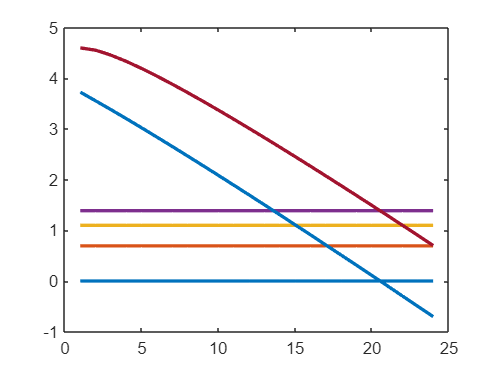

plot(log(meanmemCosts(2:5,:))','-','LineWidth',2);